outdir = "./output/jobs/allrisk_base_pairwise_small";
rawdir = fullfile(outdir, "raw/chunk_1");

accent = "surplus";
invest_cat = "advance_capacity";
all_cats = {'advance_capacity', 'improved_early_warning', ...
            'neglected_pathogen_rd', 'universal_flu_rd'};
accents = {'bcr", "surplus'};

all_files = struct2table(dir(rawdir));
all_files = all_files(~contains(all_files.name, "_prevac"), :);
all_files = all_files(~contains(all_files.name, "_prec1"), :);
all_files.fp = fullfile(all_files.folder, all_files.name);
all_files = all_files(:, {'name', 'fp'});

% Add scenario categories
for i = 1:length(all_cats)
    all_files.(all_cats{i}) = contains(all_files.name, all_cats{i});
end

surplus_files = all_files(contains(all_files.name, 'surplus'), :);
rel_sum_files = surplus_files(contains(surplus_files.name, "_relative_sums.mat"), :);
p_table_files = surplus_files(contains(surplus_files.name, "_pandemic_table"), :);

[compl_raw, compl_perc, pos_sample, neg_sample] = get_complementarity_vec("advance_capacity", "improved_early_warning", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
histogram(compl_perc, 'Normalization', 'probability');

I understand why advance capacity and improved early warning can be both complements and substitutes, depending on order of true and false positives.

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("advance_capacity", "neglected_pathogen_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[adv_cap_p_table, neglect_path_p_table] = load_pand_tables("advance_capacity", "neglected_pathogen_rd", p_table_files, all_cats)

mean(compl_perc)

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

Let's take the actual negative ones and plot the lines under the different scenarios so we can see it. Will have to think about best chart to clearly demonstrate complementarity.

Actually I think better to use a toy example.

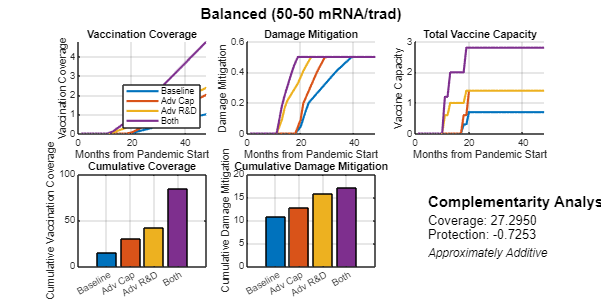

%% Configuration Parameters
disease_duration = 4 * 12;
months_arr = 1:disease_duration;

% Scenario definitions for three cases
% Case 1: Balanced (50-50)
base_split_bal = 0.5;
% Case 2: Unbalanced (75-25) 
base_split_unbal = 0.75;
% Case 3: Unbalanced (25-75)

% Case 4: No R&D speedup

base_cap_total = 2;
adv_cap_total = 2;

% Model parameters
params = struct();
params.f_m = 0.3;
params.g_m = 0.4;
params.f_o = 0.3;
params.g_o = 0.4;
params.P0 = 20;
params.universal_flu_rd = struct();
params.universal_flu_rd.initial_share_ufv = 0;
params.univ_flu_vax_eff_multiplier = 0.5;
params.gamma = 0.5;
params.tau_m = 2;
params.tau_o = 8;
params.conservative = 1;

ufv_protection = 0;
is_false = false;
num_events = 1;

%% Run simulations for all four cases
results_bal = run_scenarios(base_split_bal, base_cap_total, adv_cap_total, ...
    params, months_arr, ufv_protection, is_false, num_events, false);

results_unbal_mrna = run_scenarios(base_split_unbal, base_cap_total, adv_cap_total, ...
    params, months_arr, ufv_protection, is_false, num_events, false);

results_unbal_trad = run_scenarios(1 - base_split_unbal, base_cap_total, adv_cap_total, ...
    params, months_arr, ufv_protection, is_false, num_events, false);

results_no_speed = run_scenarios(base_split_bal, base_cap_total, adv_cap_total, ...
    params, months_arr, ufv_protection, is_false, num_events, true);

%% Visualization
colors = lines(4);
labels = {'Baseline', 'Adv Cap', 'Adv R&D', 'Both'};

% Figure 1: Balanced (50-50)
figure('Position', [100, 100, 1600, 800]);

subplot(2,3,1);
plot_time_series(results_bal, months_arr, 'vax_curve', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccination Coverage');
title('Vaccination Coverage');
legend(labels, 'Location', 'southeast');
grid on;

subplot(2,3,2);
plot_time_series(results_bal, months_arr, 'h_arr', colors);
xlabel('Months from Pandemic Start');
ylabel('Damage Mitigation');
title('Damage Mitigation');
grid on;

subplot(2,3,3);
plot_time_series(results_bal, months_arr, 'cap_tot', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccine Capacity');
title('Total Vaccine Capacity');
grid on;

subplot(2,3,4);
[comp_cov] = plot_cumulative_bar(results_bal, 'vax_curve', labels, colors);
ylabel('Cumulative Vaccination Coverage');
title('Cumulative Coverage');
grid on;

subplot(2,3,5);
[comp_prot] = plot_cumulative_bar(results_bal, 'h_arr', labels, colors);
ylabel('Cumulative Damage Mitigation');
title('Cumulative Damage Mitigation');
grid on;

subplot(2,3,6);
axis off;
text(0.1, 0.7, 'Complementarity Analysis:', 'FontSize', 14, 'FontWeight', 'bold');
text(0.1, 0.5, sprintf('Coverage: %.4f', comp_cov), 'FontSize', 12);
text(0.1, 0.35, sprintf('Protection: %.4f', comp_prot), 'FontSize', 12);
if comp_cov > 0.01 && comp_prot > 0.01
    interp = 'Superadditive (Complementary)';
elseif comp_cov < -0.01 && comp_prot < -0.01
    interp = 'Subadditive (Substitutes)';
else
    interp = 'Approximately Additive';
end
text(0.1, 0.15, interp, 'FontSize', 11, 'FontAngle', 'italic');

sgtitle('Balanced (50-50 mRNA/trad)', 'FontSize', 14, 'FontWeight', 'bold');
saveas(gcf, './output/tests/adv_cap_rd_comp_test_bal.jpg');

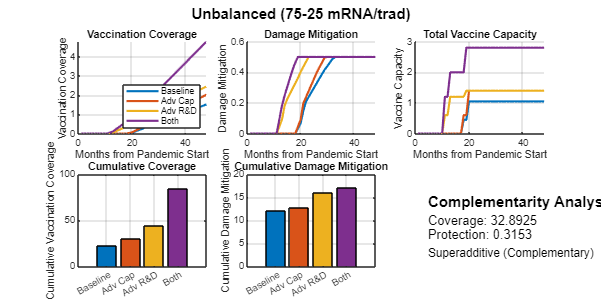



% Figure 2: Unbalanced (75-25)
figure('Position', [100, 100, 1600, 800]);

subplot(2,3,1);
plot_time_series(results_unbal_mrna, months_arr, 'vax_curve', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccination Coverage');
title('Vaccination Coverage');
legend(labels, 'Location', 'southeast');
grid on;

subplot(2,3,2);
plot_time_series(results_unbal_mrna, months_arr, 'h_arr', colors);
xlabel('Months from Pandemic Start');
ylabel('Damage Mitigation');
title('Damage Mitigation');
grid on;

subplot(2,3,3);
plot_time_series(results_unbal_mrna, months_arr, 'cap_tot', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccine Capacity');
title('Total Vaccine Capacity');
grid on;

subplot(2,3,4);
[comp_cov] = plot_cumulative_bar(results_unbal_mrna, 'vax_curve', labels, colors);
ylabel('Cumulative Vaccination Coverage');
title('Cumulative Coverage');
grid on;

subplot(2,3,5);
[comp_prot] = plot_cumulative_bar(results_unbal_mrna, 'h_arr', labels, colors);
ylabel('Cumulative Damage Mitigation');
title('Cumulative Damage Mitigation');
grid on;

subplot(2,3,6);
axis off;
text(0.1, 0.7, 'Complementarity Analysis:', 'FontSize', 14, 'FontWeight', 'bold');
text(0.1, 0.5, sprintf('Coverage: %.4f', comp_cov), 'FontSize', 12);
text(0.1, 0.35, sprintf('Protection: %.4f', comp_prot), 'FontSize', 12);
if comp_cov > 0.01 && comp_prot > 0.01
    interp = 'Superadditive (Complementary)';
elseif comp_cov < -0.01 && comp_prot < -0.01
    interp = 'Subadditive (Substitutes)';
else
    interp = 'Approximately Additive';
end
text(0.1, 0.15, interp, 'FontSize', 11);

sgtitle('Unbalanced (75-25 mRNA/trad)', 'FontSize', 14, 'FontWeight', 'bold');
saveas(gcf, './output/tests/adv_cap_rd_comp_test_unbal_mrna.jpg');

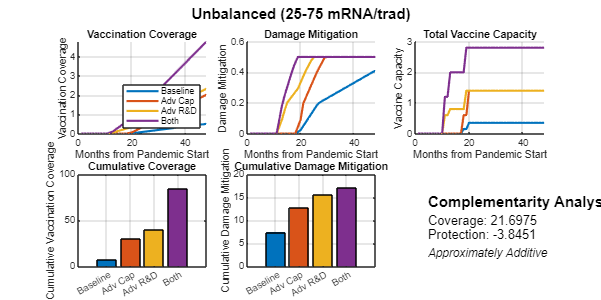



% Figure 3: Unbalanced (25-75)
figure('Position', [100, 100, 1600, 800]);

subplot(2,3,1);
plot_time_series(results_unbal_trad, months_arr, 'vax_curve', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccination Coverage');
title('Vaccination Coverage');
legend(labels, 'Location', 'southeast');
grid on;

subplot(2,3,2);
plot_time_series(results_unbal_trad, months_arr, 'h_arr', colors);
xlabel('Months from Pandemic Start');
ylabel('Damage Mitigation');
title('Damage Mitigation');
grid on;

subplot(2,3,3);
plot_time_series(results_unbal_trad, months_arr, 'cap_tot', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccine Capacity');
title('Total Vaccine Capacity');
grid on;

subplot(2,3,4);
[comp_cov] = plot_cumulative_bar(results_unbal_trad, 'vax_curve', labels, colors);
ylabel('Cumulative Vaccination Coverage');
title('Cumulative Coverage');
grid on;

subplot(2,3,5);
[comp_prot] = plot_cumulative_bar(results_unbal_trad, 'h_arr', labels, colors);
ylabel('Cumulative Damage Mitigation');
title('Cumulative Damage Mitigation');
grid on;

subplot(2,3,6);
axis off;
text(0.1, 0.7, 'Complementarity Analysis:', 'FontSize', 14, 'FontWeight', 'bold');
text(0.1, 0.5, sprintf('Coverage: %.4f', comp_cov), 'FontSize', 12);
text(0.1, 0.35, sprintf('Protection: %.4f', comp_prot), 'FontSize', 12);
if comp_cov > 0.01 && comp_prot > 0.01
    interp = 'Superadditive (Complementary)';
elseif comp_cov < -0.01 && comp_prot < -0.01
    interp = 'Subadditive (Substitutes)';
else
    interp = 'Approximately Additive';
end
text(0.1, 0.15, interp, 'FontSize', 11, 'FontAngle', 'italic');

sgtitle('Unbalanced (25-75 mRNA/trad)', 'FontSize', 14, 'FontWeight', 'bold');
saveas(gcf, './output/tests/adv_cap_rd_comp_test_unbal_trad.jpg');

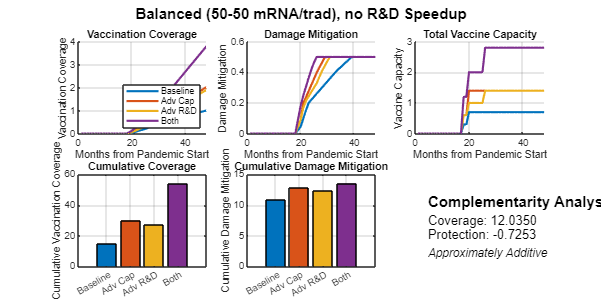



% Figure 4: No R&D Speedup
figure('Position', [100, 100, 1600, 800]);

subplot(2,3,1);
plot_time_series(results_no_speed, months_arr, 'vax_curve', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccination Coverage');
title('Vaccination Coverage');
legend(labels, 'Location', 'southeast');
grid on;

subplot(2,3,2);
plot_time_series(results_no_speed, months_arr, 'h_arr', colors);
xlabel('Months from Pandemic Start');
ylabel('Damage Mitigation');
title('Damage Mitigation');
grid on;

subplot(2,3,3);
plot_time_series(results_no_speed, months_arr, 'cap_tot', colors);
xlabel('Months from Pandemic Start');
ylabel('Vaccine Capacity');
title('Total Vaccine Capacity');
grid on;

subplot(2,3,4);
[comp_cov] = plot_cumulative_bar(results_no_speed, 'vax_curve', labels, colors);
ylabel('Cumulative Vaccination Coverage');
title('Cumulative Coverage');
grid on;

subplot(2,3,5);
[comp_prot] = plot_cumulative_bar(results_no_speed, 'h_arr', labels, colors);
ylabel('Cumulative Damage Mitigation');
title('Cumulative Damage Mitigation');
grid on;

subplot(2,3,6);
axis off;
text(0.1, 0.7, 'Complementarity Analysis:', 'FontSize', 14, 'FontWeight', 'bold');
text(0.1, 0.5, sprintf('Coverage: %.4f', comp_cov), 'FontSize', 12);
text(0.1, 0.35, sprintf('Protection: %.4f', comp_prot), 'FontSize', 12);
if comp_cov > 0.01 && comp_prot > 0.01
    interp = 'Superadditive (Complementary)';
elseif comp_cov < -0.01 && comp_prot < -0.01
    interp = 'Subadditive (Substitutes)';
else
    interp = 'Approximately Additive';
end
text(0.1, 0.15, interp, 'FontSize', 11, 'FontAngle', 'italic');

sgtitle('Balanced (50-50 mRNA/trad), no R&D Speedup', 'FontSize', 14, 'FontWeight', 'bold');
saveas(gcf, './output/tests/adv_cap_rd_comp_test_bal_no_speedup.jpg');


%% Helper Functions
function results = run_scenarios(base_split, base_cap_total, adv_cap_total, ...
    params, months_arr, ufv_protection, is_false, num_events, no_speedup)
    
    base_cap_m = base_cap_total * base_split;
    base_cap_o = base_cap_total * (1 - base_split);
    
    % Four scenarios: baseline, adv_cap, adv_rd, both
    base_caps_m = [base_cap_m, base_cap_m, base_cap_m, base_cap_m];
    base_caps_o = [base_cap_o, base_cap_o, base_cap_o, base_cap_o];
    
    adv_caps_m = [0, adv_cap_total * (1-base_split), 0, adv_cap_total * (1-base_split)];
    adv_caps_o = [0, adv_cap_total * base_split, 0, adv_cap_total * base_split];
    
    ind_m_vals = [1, 1, 1, 1];
    ind_o_vals = [0, 0, 1, 1];
    
    if no_speedup
        tau_rd_vals = [18, 18, 18, 18];
    else
        tau_rd_vals = [18, 18, 11, 11];
    end
    
    results = cell(4, 1);
    
    for i = 1:4
        x_m_tau = base_caps_m(i) + adv_caps_m(i);
        x_o_tau = base_caps_o(i) + adv_caps_o(i);
        
        [cap_m, cap_o] = get_pandemic_capacity(months_arr, tau_rd_vals(i), tau_rd_vals(i), ...
            params, ind_m_vals(i), ind_o_vals(i), x_m_tau, x_o_tau);
        cap_tot = cap_m + cap_o;
        
        max_vax_rate = 5;
        cap_per_period = cap_tot / params.P0;
        response_available = (tau_rd_vals(i) <= months_arr);
        initial_ufv = params.universal_flu_rd.initial_share_ufv .* ufv_protection;
        
        % Phase 1: UFV
        cap_for_ufv = cumsum(cap_per_period .* ufv_protection .* ~response_available, 2);
        ufv_holders = min(initial_ufv + cap_for_ufv, max_vax_rate);
        ufv_at_response_start = max(ufv_holders, [], 2);
        unvaccinated_at_response_start = max(0, max_vax_rate - ufv_at_response_start);
        
        % Phase 2: Response vaccine
        cap_for_response = cumsum(cap_per_period .* response_available, 2);
        new_response_from_unvax = min(cap_for_response, unvaccinated_at_response_start);
        remaining_cap = max(0, cap_for_response - unvaccinated_at_response_start);
        replacements = min(remaining_cap, ufv_at_response_start);
        
        response_vax_fraction = new_response_from_unvax + replacements;
        ufv_only_fraction = max(0, ufv_holders - replacements);
        total_protected = min(ufv_only_fraction + response_vax_fraction, max_vax_rate);
        
        if params.conservative == 1
            ufv_only_fraction = [initial_ufv, ufv_only_fraction(:, 1:end-1)] .* ~is_false;
            response_vax_fraction = [zeros(num_events, 1), response_vax_fraction(:, 1:end-1)] .* ~is_false;
            total_protected = ufv_only_fraction + response_vax_fraction;
        end
        
        % Calculate protection
        ufv_share = ufv_only_fraction ./ total_protected;
        ufv_share(total_protected == 0) = 0;
        eff_multiplier = 1 - ufv_share .* (1 - params.univ_flu_vax_eff_multiplier);
        h_arr = params.gamma .* eff_multiplier .* h(total_protected);
        
        results{i} = struct();
        results{i}.vax_curve = total_protected;
        results{i}.h_arr = h_arr;
        results{i}.cap_tot = cap_tot;
    end
end

function plot_time_series(results, months_arr, field_name, colors)
    hold on;
    for i = 1:4
        data = results{i}.(field_name);
        if size(data, 1) > 1
            data = data(1,:);
        end
        plot(months_arr, data, 'LineWidth', 2, 'Color', colors(i,:));
    end
    xlim([0 length(months_arr)]);
end

function comp = plot_cumulative_bar(results, field_name, labels, colors)
    cum_vals = zeros(4, 1);
    for i = 1:4
        data = results{i}.(field_name);
        if size(data, 1) > 1
            data = data(1,:);
        end
        cum_vals(i) = sum(data);
    end
    
    bar(cum_vals, 'FaceColor', 'flat', 'CData', colors);
    set(gca, 'XTickLabel', labels);
    
    % Calculate and return complementarity
    comp = cum_vals(4) - cum_vals(1) - (cum_vals(2) - cum_vals(1)) - (cum_vals(3) - cum_vals(1));
end

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("advance_capacity", "universal_flu_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[adv_cap_p_table, univ_flu_p_table] = load_pand_tables("advance_capacity", "universal_flu_rd", p_table_files, all_cats)

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("improved_early_warning", "universal_flu_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[early_warn_p_table, univ_flu_p_table] = load_pand_tables("improved_early_warning", "universal_flu_rd", p_table_files, all_cats);

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

[compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec("improved_early_warning", "neglected_pathogen_rd", ...
                                                                          42, rel_sum_files, p_table_files, ...
                                                                          all_cats);
[early_warn_p_table, neglect_rd_p_table] = load_pand_tables("improved_early_warning", "neglected_pathogen_rd", p_table_files, all_cats);

neg_rel_sums = compl_raw(unique(neg_sample.sim_num));
pos_rel_sums = compl_raw(unique(pos_sample.sim_num));
histogram(compl_perc, 'Normalization', 'probability');

function [invest_one_p_table, invest_two_p_table] =  load_pand_tables(invest_one, invest_two, p_table_files, all_cats)

    invest_one_idx = contains(p_table_files.name, invest_one);
    invest_two_idx = contains(p_table_files.name, invest_two);
    alone_idx = table2array(sum(p_table_files(:, all_cats), 2) == 1);

    invest_one_p_table = load(char(p_table_files.fp(invest_one_idx & alone_idx)));
    invest_one_p_table = invest_one_p_table.pandemic_table;
    invest_two_p_table = load(char(p_table_files.fp(invest_two_idx & alone_idx)));
    invest_two_p_table = invest_two_p_table.pandemic_table;
end

function [compl_raw, compl_perc, neg_sample, pos_sample] = get_complementarity_vec(...
    invest_one, invest_two, seed, results_files, p_table_files, all_cats)

    invest_one_idx = contains(results_files.name, invest_one);
    invest_two_idx = contains(results_files.name, invest_two);
    alone_idx = table2array(sum(results_files(:, all_cats), 2) == 1);

    invest_one_rel_sums = load(char(results_files.fp(invest_one_idx & alone_idx)));
    invest_two_rel_sums = load(char(results_files.fp(invest_two_idx & alone_idx)));
    combined_rel_sums = load(char(results_files.fp(invest_one_idx & invest_two_idx)));

    invest_one_benefits = invest_one_rel_sums.scenario_sum_table.benefits_vaccine_full;
    invest_two_benefits = invest_two_rel_sums.scenario_sum_table.benefits_vaccine_full;
    combined_rel_sums = combined_rel_sums.scenario_sum_table.benefits_vaccine_full;

    standalone_benefits_sum = invest_one_benefits + invest_two_benefits;
    compl_raw = combined_rel_sums - standalone_benefits_sum;
    compl_perc = 100 * compl_raw ./ standalone_benefits_sum;
    compl_perc(standalone_benefits_sum == 0 & combined_rel_sums == 0) = 0;

    combined_pandemic_table = load(char(p_table_files.fp(invest_one_idx & invest_two_idx)));
    combined_pandemic_table = combined_pandemic_table.pandemic_table;
    
    rng(seed);
    neg_idx = randsample(find(compl_perc < 0), 50, false);
    pos_idx = randsample(find(compl_perc > 0), 50, false);

    neg_sample = combined_pandemic_table(ismember(combined_pandemic_table.sim_num, neg_idx), :);
    pos_sample = combined_pandemic_table(ismember(combined_pandemic_table.sim_num, pos_idx), :);
end